G2_sitl = [G2_t G2_e];
G2_sitl(4,1) = tf([47.4 261.5],[1 0.1175]);
G2_sitl(4,2) = tf([1.661 27.46],[1 0.2174]);
G2_sitl

G2_sitl =
 
  From input "Throttle" to output...
                  0.1793 s + 5.528
   Pitch rate:  ---------------------
                s^2 + 1.644 s + 1.819
 
                  17.61 s - 8.041
   Velocity:  ------------------------
              s^2 + 0.13 s + 4.777e-08
 
                   47.4 s + 261.5
   Altitude:  -------------------------
              s^2 + 0.1175 s + 0.004125
 
       47.4 s + 261.5
   4:  --------------
         s + 0.1175
 
  From input "Elevator deflection" to output...
                     14.86 s + 3.881
   Pitch rate:  -------------------------
                s^2 + 8.846 s + 3.508e-11
 
                  7.532 s + 0.8488
   Velocity:  -------------------------
              s^2 + 0.1744 s + 0.009645
 
                  1.661 s + 27.46
   Altitude:  ------------------------
              s^2 + 0.2174 s + 0.01848
 
       1.661 s + 27.46
   4:  ---------------
         s + 0.2174
 
Continuous-time transfer function.



damp(G2_sitl)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.97e-12                 1.00e+00       3.97e-12         2.52e+11    
 -3.67e-07                 1.00e+00       3.67e-07         2.72e+06    
 -5.87e-02 + 2.60e-02i     9.14e-01       6.42e-02         1.70e+01    
 -5.87e-02 - 2.60e-02i     9.14e-01       6.42e-02         1.70e+01    
 -8.72e-02 + 4.52e-02i     8.88e-01       9.82e-02         1.15e+01    
 -8.72e-02 - 4.52e-02i     8.88e-01       9.82e-02         1.15e+01    
 -1.17e-01                 1.00e+00       1.17e-01         8.51e+00    
 -1.30e-01                 1.00e+00       1.30e-01         7.69e+00    
 -1.09e-01 + 8.16e-02i     8.00e-01       1.36e-01         9.20e+00    
 -1.09e-01 - 8.16e-02i     8.00e-01       1.36e-01         9.20e

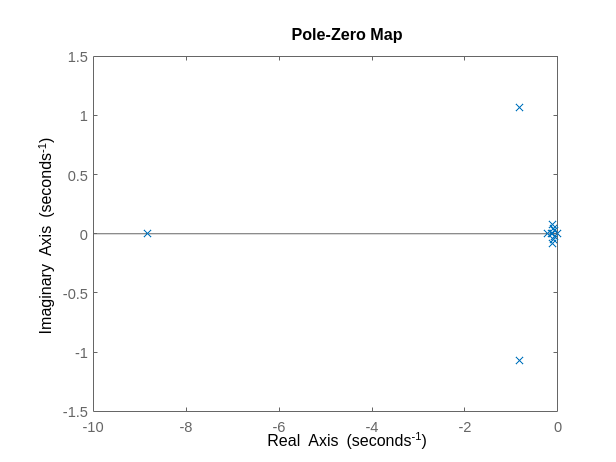

pzmap(G2_sitl)

G3_sitl = [G3_t G3_e];
G3_sitl(4,1) = tf([0.009637 8.793],[1 -0.02187]);
G3_sitl(4,2) = tf([-4.913 33.15],[1 0.9224]);
G3_sitl

G3_sitl =
 
  From input "Throttle" to output...
                  -34.68 s + 130.5
   Pitch rate:  ---------------------
                s^2 + 168.2 s - 29.48
 
                  21.11 s - 9.148
   Velocity:  -----------------------
              s^2 + 0.5425 s - 0.1124
 
                  0.009637 s + 8.793
   Altitude:  --------------------------
              s^2 - 0.02187 s + 0.002889
 
       0.009637 s + 8.793
   4:  ------------------
          s - 0.02187
 
  From input "Elevator deflection" to output...
                  12.31 s - 3.761
   Pitch rate:  --------------------
                s^2 + 6.719 s - 1.15
 
                 5.012 s - 12.95
   Velocity:  ----------------------
              s^2 + 0.2334 s + 1.019
 
                  -4.913 s + 33.15
   Altitude:  ------------------------
              s^2 + 0.9224 s - 0.06914
 
       -4.913 s + 33.15
   4:  ----------------
          s + 0.9224
 
Continuous-time transfer function.



damp(G3_sitl)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  2.19e-02                -1.00e+00       2.19e-02        -4.57e+01    
  1.09e-02 + 5.26e-02i    -2.03e-01       5.38e-02        -9.14e+01    
  1.09e-02 - 5.26e-02i    -2.03e-01       5.38e-02        -9.14e+01    
  6.97e-02                -1.00e+00       6.97e-02        -1.43e+01    
  1.60e-01                -1.00e+00       1.60e-01        -6.25e+00    
  1.67e-01                -1.00e+00       1.67e-01        -5.99e+00    
  1.75e-01                -1.00e+00       1.75e-01        -5.71e+00    
 -7.03e-01                 1.00e+00       7.03e-01         1.42e+00    
 -9.22e-01                 1.00e+00       9.22e-01         1.08e+00    
 -9.92e-01                 1.00e+00       9.92e-01         1.01e

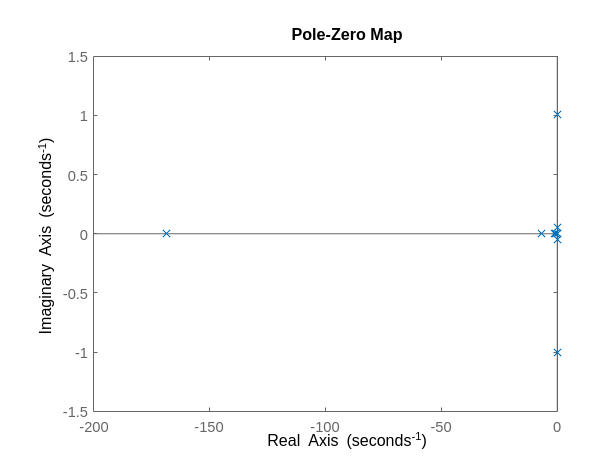

pzmap(G3_sitl)



% time 
wp = sqrt(0.004125)

wp = 0.0642

fp = wp/(2*3.14)

fp = 0.0102

ws = sqrt(1.819)

ws = 1.3487

fs = ws/(2*3.14)

fs = 0.2148



%freq 
wp = sqrt(0.1124)

wp = 0.3353

fp = wp/(2*3.14)

fp = 0.0534

ws = sqrt(1.15)

ws = 1.0724

fs = ws/(2*3.14)

fs = 0.1708